# 入力の作成方法

% % MPC controller
% % ts探し
tic
% rng(0,'twister');
% ts = 0;
% % 入力のサンプルから評価
% fun = @(p_monte) (p_monte - agent.reference.result.state.p)'*Q_monte*(p_monte - agent.reference.result.state.p); 
% Rmax = 0.269 * 9.81 / 4;  % 乱数の値の範囲
sample = 100;   % サンプル数
horizon = 10;
% 入力 u
% u1 = zeros(sample, 2); % 入力，評価関数の値/ 1horizon, 2h, 3h
% u2 = zeros(sample, 2);
% u3 = zeros(sample, 2);
% u4 = zeros(sample, 2);
% u1 u2 u3 u4 val
% Xdata = zeros(sample , 5);
% ホバリングから±10%の範囲
a = 0.269 * 9.81 / 4 - 0.269 * 9.81 / 4 * 0.1;
b = 0.269 * 9.81 / 4 + 0.269 * 9.81 / 4 * 0.1;
% r = (b-a).*rand(1000,1) + a;
% u1 = (b-a).*rand(horizon, sample) + a
% u1 = repmat((b-a).*rand(sample,1) + a, horizon*4, 1)    % (horizon * sample , 1)
u1 = (b-a).*rand(horizon,sample) + a;
u2 = (b-a).*rand(horizon,sample) + a;
u3 = (b-a).*rand(horizon,sample) + a;
u4 = (b-a).*rand(horizon,sample) + a;
% size(u1)
u1 = repmat(reshape(u1, [1, size(u1)]), 4, 1)

u1 = u1(:,:,1) =

    0.6245    0.6674    0.6563    0.6192    0.7005    0.7245    0.6656    0.6166    0.5943    0.5979
    0.6245    0.6674    0.6563    0.6192    0.7005    0.7245    0.6656    0.6166    0.5943    0.5979
    0.6245    0.6674    0.6563    0.6192    0.7005    0.7245    0.6656    0.6166    0.5943    0.5979
    0.6245    0.6674    0.6563    0.6192    0.7005    0.7245    0.6656    0.6166    0.5943    0.5979


u1(:,:,2) =

    0.6139    0.6523    0.6857    0.6322    0.6979    0.6493    0.6557    0.6114    0.6526    0.6674
    0.6139    0.6523    0.6857    0.6322    0.6979    0.6493    0.6557    0.6114    0.6526    0.6674
    0.6139    0.6523    0.6857    0.6322    0.6979    0.6493    0.6557    0.6114    0.6526    0.6674
    0.6139    0.6523    0.6857    0.6322    0.6979    0.6493    0.6557    0.6114    0.6526    0.6674


u1(:,:,3) =

    0.6168    0.6687    0.6933    0.6467    0.7011    0.6351    0.6638    0.6082    0.6232    0.6636
    0.6168    0.6687    0.6933    0.6467   

% u2 = reshape(u2, [1, size(u2)]);
% u3 = reshape(u3, [1, size(u3)]);
% u4 = reshape(u4, [1, size(u4)]);
% u = reshape(ux, [1, size(ux)]);
% u1 = reshape(4, u1)
% u = [u1; u2; u3; u4]
size(u)   % 4 * horizon * sample

ans =      4    25   100


Adata = zeros(4, horizon, sample)

Adata = Adata(:,:,1) =

     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


Adata(:,:,2) =

     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


Adata(:,:,3) =

     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


Adata(:,:,4) =

     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0 

size(Adata)

ans =      4    10   100



% u1(: ,:) = [(b-a).*rand(sample,1) + a (b-a).*rand(sample,1) + a ];
% u2(: ,:) = [(b-a).*rand(sample,1) + a (b-a).*rand(sample,1) + a ];
% u3(: ,:) = [(b-a).*rand(sample,1) + a (b-a).*rand(sample,1) + a ];
% u4(: ,:) = [(b-a).*rand(sample,1) + a (b-a).*rand(sample,1) + a ];

% 
% Xdata(2, 1:3)
%   % sample * 8 
% % Adata = zeros(sample, 2);
% % 算出
% % Xdata(:, 5) = arrayfun(fun, u1(:), u2(:), u3(:), u4(:));               % 評価関数
% % % Adata(Adata(:, 2)==0, :) = []; % 制約なし
% % [~,min_index] = min(Xdata(:, 2));   % 最小値算出
% % u = Xdata(min_index, 1) % 入力の取得
toc

経過時間は 0.543701 秒です。


sigma = 0.15;
a = 0.269 * 9.81 / 4 - 0.269 * 9.81 / 4 * sigma  

a = 0.5608

b = 0.269 * 9.81 / 4 + 0.269 * 9.81 / 4 * sigma

b = 0.7587


aa = (1-sigma) * 0.269*9.81/4

aa = 0.5608

bb = (1+sigma) * 0.269*9.81/4

bb = 0.7587


A = diag([1 1 1])

A =      1     0     0
     0     1     0
     0     0     1


B= diag([1; 1; 1])

B =      1     0     0
     0     1     0
     0     0     1


% Q_monte = eye(3) * 0.5;
% N = 10;
% p_monte = [randi(N) randi(N) -2]'
% fun = @(p_monte) (p_monte - [10;10;10])'*Q_monte*(p_monte - [10;10;10]); 
% Xdata = fun(p_monte)   
% p_monte_monte = p_monte'

% 
% Fsub = @(z_monte) z_monte > 0
% Fsub(p_monte_monte(:, 3))

## cell配列講座

sample = 5;
P_monte = cell(sample, sample);
% P_monte{1,1} = [2,3,4]
% P_monte{1,1} = 10
% P_monte{2,1} = [2,3,4, 5, 6, 10]
% P_monte{4,2} = [2,54,1,4,56]
b = 10;
a = 0;
for i = 1: sample
    for k = 1:sample
        P_monte{i, k} = ((b-a).*rand(sample,1) + a)'; 
    end
end
P_monte

P_monte = 5×5 の cell 配列
    {[6.9350 2.3513 1.6570 0.6124 5.8568]}    {[2.9126 5.7993 4.9983 6.4983 1.2882]}    {[2.5401 8.7785 9.1627 6.3014 4.3223]}    {[8.0554 2.9692 9.1640 0.5728 0.5035]}    {[4.2336 5.1098 8.7771 0.0252 3.3505]}
    {[1.0211 9.6702 0.3493 6.6205 9.9644]}    {[9.2735 4.5541 4.0973 3.1496 1.8103]}    {[3.5176 7.1723 5.7029 0.5585 5.1208]}    {[7.2697 2.4537 2.5686 6.2826 4.0244]}    {[6.8873 5.2689 8.2838 9.4396 2.8210]}
    {[7.9255 7.3592 9.6447 9.0327 8.8970]}    {[1.2248 6.4155 5.0832 8.5775 2.1554]}    {[2.8074 3.6994 8.8028 3.1118 2.8132]}    {[1.9095 7.1338 2.5604 0.9441 4.7100]}    {[4.8943 4.5677 7.9515 0.0304 5.6055]}
    {[6.1274 8.0869 3.3774 6.4440 4.2942]}    {[3.3179 1.6786 5.3679 6.3000 7.0271]}    {[9.2834 9.9118 4.5169 7.2901 6.7244]}    {[7.6565 1.0143 3.7210 3.9525 3.6856]}    {[6.2843 7.6141 2.4955 9.0876 9.4053]}
    {[7.5984 6.7391 3.0207 9.4092 5.2989]}    {[7.4723 9.5630 1.4903 4.8762 6.5216]}    {[7.2282 4.4865 0.5445 9.6152 9.5403]}    {[

State_1 = P_monte(i, :);
pp = cell2mat(State_1);
State_monte = zeros(sample, 25);

% cell to double
for i = 1:sample
    State_monte(i, 1:sample*sample) = cell2mat(P_monte(i, :));
end

State_monte

State_monte =     6.9350    2.3513    1.6570    0.6124    5.8568    2.9126    5.7993    4.9983    6.4983    1.2882    2.5401    8.7785    9.1627    6.3014    4.3223    8.0554    2.9692    9.1640    0.5728    0.5035    4.2336    5.1098    8.7771    0.0252    3.3505
    1.0211    9.6702    0.3493    6.6205    9.9644    9.2735    4.5541    4.0973    3.1496    1.8103    3.5176    7.1723    5.7029    0.5585    5.1208    7.2697    2.4537    2.5686    6.2826    4.0244    6.8873    5.2689    8.2838    9.4396    2.8210
    7.9255    7.3592    9.6447    9.0327    8.8970    1.2248    6.4155    5.0832    8.5775    2.1554    2.8074    3.6994    8.8028    3.1118    2.8132    1.9095    7.1338    2.5604    0.9441    4.7100    4.8943    4.5677    7.9515    0.0304    5.6055
    6.1274    8.0869    3.3774    6.4440    4.2942    3.3179    1.6786    5.3679    6.3000    7.0271    9.2834    9.9118    4.5169    7.2901    6.7244    7.6565    1.0143    3.7210    3.9525    3.6856    6.2843    7.6141    2.4955   

% pp = cell2mat(P_monte(4, 2))
% pp(2)




% P_monte{2,1}    % 要素を値として取り出す
% P_monte(2,1)    % cell配列として取り出す
% P_monte{4,2} = [2,54,1,4,56]
% 
% P_monte{1,1} = [[1,2,3]; [4,5,6]]
% P = P_monte{1,1,1}
% 
% P = P_monte{4,2}(2:4)

## 乱数の取り方

rng('shuffle')
sigma = 0.3;
delta1 = 0.0; delta2 = 0.0; delta3 = 0.0; delta4 = 0.0;
a = 0.269 * 9.81 / 4 - 0.269 * 9.81 / 4 * sigma;           b = 0.269 * 9.81 / 4 + 0.269 * 9.81 / 4 * sigma;
sample = 10;   % サンプル数
u = (b-a).*rand(sample,4) + a

u =     0.8048    0.5824    0.4665    0.6949
    0.6678    0.5344    0.6757    0.4980
    0.5867    0.6412    0.8265    0.7013
    0.4824    0.8522    0.8006    0.5624
    0.6768    0.6132    0.7381    0.8521
    0.5377    0.7715    0.6444    0.6864
    0.6615    0.5124    0.6164    0.6104
    0.8035    0.8565    0.4726    0.7364
    0.7077    0.4836    0.6086    0.8098
    0.6391    0.5570    0.7006    0.6101


## 重み行列

diag([10.; 10.; 0; 0])

ans =     10     0     0     0
     0    10     0     0
     0     0     0     0
     0     0     0     0



Q_monte_x = 1; Q_monte_y = 1; Q_monte_z = 1000000;
Q_monte = [Q_monte_x 0 0; 0 Q_monte_y 0; 0 0 Q_monte_z]

Q_monte =            1           0           0
           0           1           0
           0           0     1000000


% Q_monte = diag([Q_monte_x, Q_monte_y, Q_monte_z])

Td = 0.1;    % 離散時間幅
Te = 20;	  % シミュレーション時間
x0 = [0.5; 0.; 0; 0; 76];% 初期状態
u0 = [0.; 0.];% 初期状態
ur = [0.;0.];% 目標速度
Xo = [3;1;0;0];  % 障害の位置　(静止障害物)
Particle_num = 1000; % サンプル数
%         sigmav = repmat(0.1, 1,Particle_num); %仮の分散値
%Csigma = 0.001;%　時間ごとに変化する分散値の上昇定数
Csigma = 0.005;%　時間ごとに変化する分散値の上昇定数
Count_sigma = 0;
uxnow =0.05;
uynow =0.05;
umax = 6.5;
remove_flag = 1;
remove_flagI = 1;
% sigma_cnt = 1: Params.H;
sigma_cnt = 2;
sigmax = repmat(0.3+Csigma*(sigma_cnt-1), Particle_num, 1)' %初期時刻

sigmax =     0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050


sigmay = repmat(0.3+Csigma*(sigma_cnt-1), Particle_num, 1)'

sigmay =     0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050    0.3050


t = 0:0.025:4;
y = (t / 4).^2

y =          0    0.0000    0.0002    0.0004    0.0006    0.0010    0.0014    0.0019    0.0025    0.0032    0.0039    0.0047    0.0056    0.0066    0.0077    0.0088    0.0100    0.0113    0.0127    0.0141    0.0156    0.0172    0.0189    0.0207    0.0225    0.0244    0.0264    0.0285    0.0306    0.0329    0.0352    0.0375    0.0400    0.0425    0.0452    0.0479    0.0506    0.0535    0.0564    0.0594    0.0625    0.0657    0.0689    0.0722    0.0756    0.0791    0.0827    0.0863    0.0900    0.0938


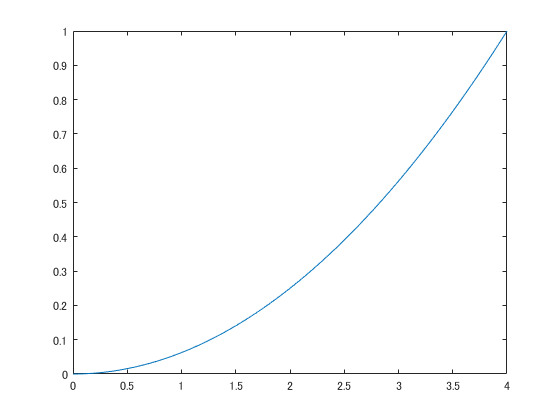

plot(t, y)

sample = 100;
fSubIndex = (1:sample)'

fSubIndex =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


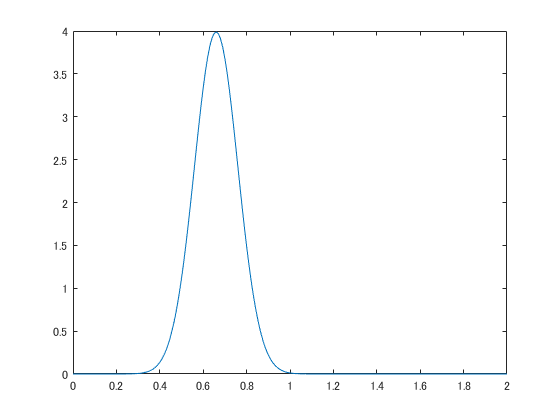

x = [0:0.01:2];
y = normpdf(x,0.269*9.81/4,0.1);
plot(x, y)

now = datetime('now');
datename = datestr(now, 'yyyymmdd_HHMMSS_FFF');
fprintf(datename + ".jpg")

20220725_124442_800.jpg

func = @(x) x + 2*x^2;
func(1,2)
arrayfun(func)
stageStateP  = arrayfun(@(L) tildeXp(:, L)'   * params.Weight.P   * tildeXp(:, L),   1:params.H-1);

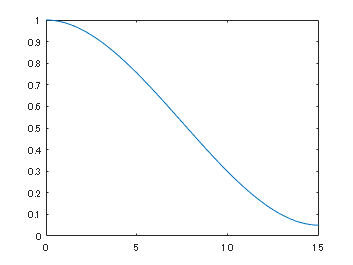

syms t real
T = 15;   % 目標到達までの時間
Tv = 0:0.1:T;
rz = 0.05;
rz0 = 1;
a = -2/T^3 * (rz-rz0);
b = 3/T^2 * (rz-rz0);
z = a*(t)^3+b*(t)^2+rz0 ; % 目標値関数
X_R = subs(z, t, Tv);
plot(Tv, X_R);

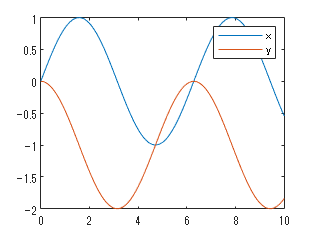

syms t real
x = sin(t);
y = cos(t)-1;

T = 10;   % 目標到達までの時間
Tv = 0:0.1:T;

X_R = subs(x, t, Tv);
Y = subs(y, t, Tv);

plot(Tv, X_R, Tv, Y)
legend("x", "y")

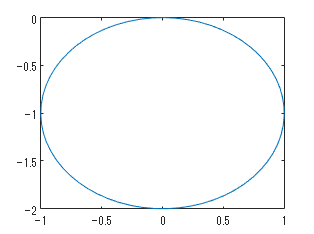


plot(X_R, Y)

H = 10;
ref = zeros(3, H);
rz = 0; % 目標
rz0 = 1.5;% スタート
T = 13; % かける時間
Tv = 0:0.1:10;
StartT = -3;
syms t real
a = -2/T^3 * (rz-rz0);
b = 3/T^2 * (rz-rz0);
z = a*(t-StartT)^3+b*(t-StartT)^2+rz0

$$z = \frac{3\,{\left(t+3\right)}^{3}}{2197}-\frac{9\,{\left(t+3\right)}^{2}}{338}+\frac{3}{2}$$

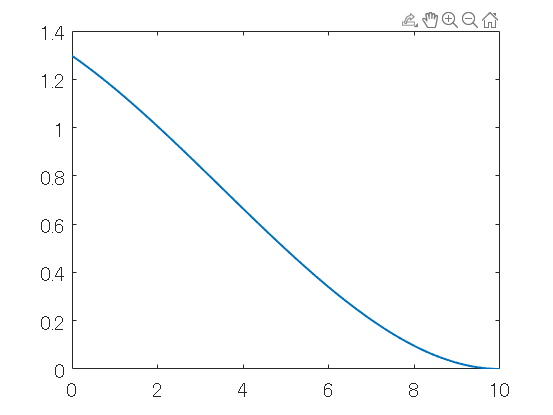

Z = subs(z, t, Tv);
plot(Tv, Z);


% 微分
zdiff = diff(z, t)

$$zdiff = \frac{9\,{\left(t+3\right)}^{2}}{2197}-\frac{9\,t}{169}-\frac{27}{169}$$

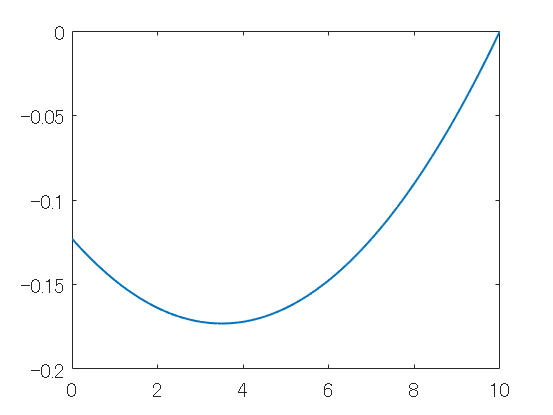

plot(Tv, subs(zdiff, t, Tv))


subs(zdiff, t, 0)

$$ans = -\frac{270}{2197}$$

%-- ホライゾンごとのreference
% ref(h) = [0;0;a*(t-StartT)^3+b*(t-StartT)^2+rz0];

syms t l real
f = t + 3 * l ^ 2;
subs(f, [t, l], [1, 2])

$$ans = 13$$


t = 1;
l = 2;
f = t + 3*l^2

f = 13

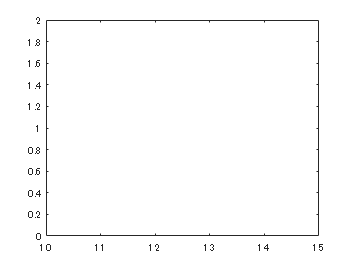

rz_R = 0.05; % 目標
rz0_R = 1;% スタート
T_R = 10; % かける時間
Tv_R = 0:0.01:T_R;
StartT_R = 0;
a_R = -2/T_R^3 * (rz_R-rz0_R);
b_R = 3/T_R^2 * (rz_R-rz0_R);
syms t real
z_R = a_R*(t-StartT_R)^3+b_R*(t-StartT_R)^2+rz0_R;
Z_R = subs(z_R, t, Tv_R);

% X
plot(Tv_R, 1, 'LineWidth', 2); ylim([0 2]);

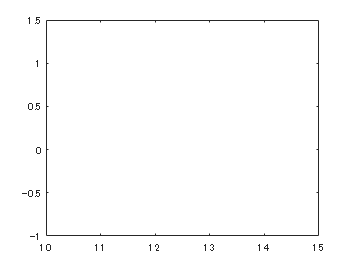

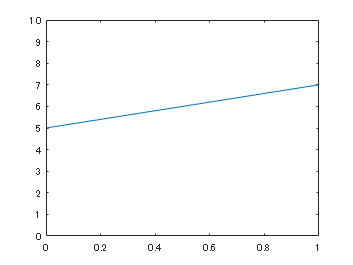

% plot(Tv_R, X_R); xlim([10 15]); hold on;

A = [1 3 29 1 3;
     2 4 21 0 92;
     2 1 0 2 1]

A =      1     3    29     1     3
     2     4    21     0    92
     2     1     0     2     1


ind = find(A(:, end) > 5)

ind = 2

% Nind = find(A(:, end) <= 5)
A(A(:, end) <= 5, :) = NaN

A =    NaN   NaN   NaN   NaN   NaN
     2     4    21     0    92
   NaN   NaN   NaN   NaN   NaN



% A(find(A(:, end) <= 5), :) = NaN

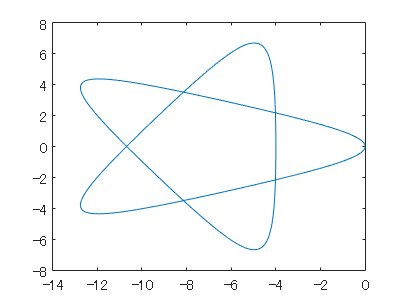

T = 0:0.1:20;
X = 5*cos(2*T/3) + 2*cos(T)-7;
Y = -5*sin(2*T/3) + 2*sin(T);
plot(X, Y)


X = 5*cos(2*0/3) + 2*cos(0)

X = 7

Y = -5*sin(2*0/3) + 2*sin(0)

Y = 0

pathJ = data.pathJ;
pathJ{1}(1,:)

ans =   311.1599  344.7297  414.1222  433.9124  352.2622  398.7282  457.1282  267.2428  359.7316  449.2610  358.6413  371.0647  309.5397  328.5377  273.3835  483.5661  375.2121  301.0672  428.8955  301.6853  301.9105  364.0643  339.7687  387.8606  341.4295  423.2322  284.1303  482.4679  297.1192  336.1558  305.1325  341.2104  521.3736  342.7916  422.8055  548.8568  462.5478  349.7931  276.4247  277.8419  443.6090  278.6321  360.6496  329.5563  276.4079  296.5664  392.1802  430.8052  398.6208  314.9234


count = 1;
sortPath = sort(pathJ{count}(1, :));
sortPath(1:10) = 1:10;

minI = mink(pathJ{1}(1,:), 10);
for L = 1:10
    minIL = find(pathJ{1}(1, :) == minI(L)); 
    pathJ{1}(1, minIL) = L; 
end
% minIL = find(pathJ{1}(1, :) == minI); 

配列のサイズがこの演算に適合しません。

関連ドキュメンテーション

% pathJ{1}(1, minIL) = minI(:); 

pathJ{1}(1,:)

for n = 1:5
 str = ['part',num2str(n),'=a',num2str(n),';'];
 eval(str)
end

使い方によるエラー eval
関数または変数 'a1' が認識されません。

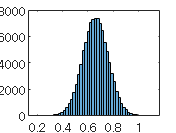

obj.input.sigma = 0.1;
obj.param.H = 10;
obj.param.particle_num = 100000;
ave1 = 0.269*9.81/4; ave2 = ave1;
ave3 = ave1; ave4 = ave1;
obj.input.u1 = obj.input.sigma.*randn(obj.param.H, obj.param.particle_num) + ave1;
obj.input.u2 = obj.input.sigma.*randn(obj.param.H, obj.param.particle_num) + ave2;
obj.input.u3 = obj.input.sigma.*randn(obj.param.H, obj.param.particle_num) + ave3;
obj.input.u4 = obj.input.sigma.*randn(obj.param.H, obj.param.particle_num) + ave4;
obj.input.u1(obj.input.u1<0) = 0;   % 負の入力を阻止
obj.input.u2(obj.input.u2<0) = 0;
obj.input.u3(obj.input.u3<0) = 0;
obj.input.u4(obj.input.u4<0) = 0;
obj.input.u(4, 1:obj.param.H, 1:obj.param.particle_num) = obj.input.u4;   % reshape
obj.input.u(3, :, :) = obj.input.u3;   
obj.input.u(2, :, :) = obj.input.u2;
obj.input.u(1, :, :) = obj.input.u1;

histogram(obj.input.u(1,1,:), 50)

obj.input.sigma

ans = 0.1000

A = 1:10

A =      1     2     3     4     5     6     7     8     9    10


B = [2, 3, 9]

B =      2     3     9


% C = ismember(A, B)
I = find(ismember(A, B)==0)

I =      1     4     5     6     7     8    10


% find(A == B)

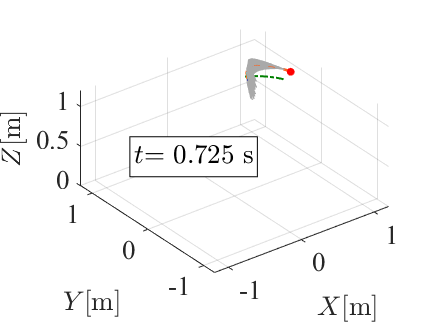

path_count = size(data.pathJ{count},2);
for j = 1:path_count
	plot3(data.path{count}(1,:,j),data.path{count}(2,:,j),data.path{count}(3,:,j),'Color',Color_map(ceil(pathJN{count}(1,j)*1000+0.0001),:), 'LineWidth',1);
	hold on; 
end 
plot3(data.xr{count}(1,:), data.xr{count}(2,:), data.xr{count}(3,:), '-.', 'Color', '#008000');
plot3(data.state(count, 2), data.state(count, 3), data.state(count, 4), '.', 'MarkerSize', 20, 'Color', 'red');

plot3(data.bestx(count,:),data.besty(count,:), data.bestz(count, :),'--','Color',[255,94,25]/255,'LineWidth',2);

str = ['$$t$$= ',num2str(data.state(count,1),'%.3f'),' s'];
text(-0.35,1.35,str,'FontSize',20,'Interpreter', 'Latex','BackgroundColor',[1 1 1],'EdgeColor',[0 0 0])
grid on
% 		ax.YLim = [-0.5 2];
% 		ax.XLim = [-0.5 2];
ax.YLim = [-1.2 1.2];
ax.XLim = [-1.2 1.2];
ax.ZLim = [0 1.2];
fig.Units = 'normalized';
set(gca,'FontSize',20,'FontName','Times');
xlabel('$$X$$[m]','Interpreter', 'Latex','FontSize',20);
ylabel('$$Y$$[m]','Interpreter', 'Latex','FontSize',20);
zlabel('$$Z$$[m]','Interpreter', 'Latex','FontSize',20)
%     legend({'Reference'},'FontSize',18,'Location','northeast');
filename = ['Animation_2_2_',num2str(count),];
Xleng = ax.XLim(1,2) - ax.XLim(1,1);
Yleng = ax.YLim(1,2) - ax.YLim(1,1);
Zleng = ax.ZLim(1,2) - ax.ZLim(1,1);
pbaspect([Xleng,Yleng,Zleng]);
ax.OuterPosition = [0.0,0.0,1.15,1.];
ax.Position = [0.08,0.14,0.89,0.778];
% %     fig.OuterPosition = [-0.056155913978495,0.039753088660446,1.137096774193548,0.995295763873069];
fig.Position = [0.17143,0.2074,0.5,0.5102];
%     saveas(gcf,strcat(Outputdir,'/eps/Animation1/',filename),'epsc');
%     savefig(gcf,strcat(Outputdir,'/fig/Animation1/',filename),'compact');
saveas(gcf,strcat(Outputdir,'/png/Animation1/',filename),'png');

Color_map = (169/255)*ones(1000000,3);  % 灰色のカラーマップの作成
% 寒色：良い評価、暖色：悪い評価
Color_map(1:10,:) = jet(10);            % 評価値の上から10個をカラーマップの色付け.
%     Color_map(1:data.param.particle_num/2, :) = jet(data.param.particle_num/2);
writerObj=VideoWriter(strcat(Outputdir,'/video/animation_v10_3d'));

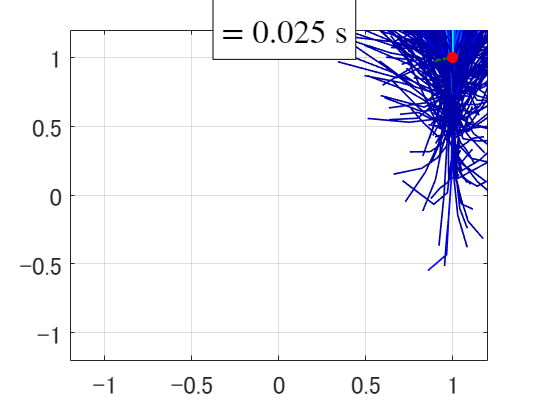

open(writerObj);

countMax = size(data.pathJ,2);
for count = 1:countMax
    %%
%         count = 50;
    clf(figure(999))
	fig = figure(999);
	ax = gca;
%         patch([1 5 5 1],[-0.5 -0.5 1 1],'black','Facealpha',0.2);
%         hold on
%         plot(data.state(:,10),data.state(:,11),'-','Color',[0,0,0]/255,'LineWidth',4);
        
%         hold on;
	% 予測経路のplot(ホライズン)
    path_count = size(data.pathJ{count},2);
	for j = 1:path_count
		plot(data.path{count}(1,:,j),data.path{count}(3,:,j),'Color',Color_map(ceil(pathJN{count}(1,j)*1000+0.0001),:), 'LineWidth',1);
		hold on; 
    end 
    plot(data.xr{count}(1,:), data.xr{count}(3,:), '-.', 'Color', '#008000');
    plot(data.state(count, 2), data.state(count, 4), '.', 'MarkerSize', 20, 'Color', 'red');

% 	plot(data.bestx(count,:),data.bestz(count, :), ,'--','Color',[255,94,25]/255,'LineWidth',2);
	str = ['$$t$$= ',num2str(data.state(count,1),'%.3f'),' s'];
	text(-0.35,1.35,str,'FontSize',20,'Interpreter', 'Latex','BackgroundColor',[1 1 1],'EdgeColor',[0 0 0])
	grid on
% 		ax.YLim = [-0.5 2];
% 		ax.XLim = [-0.5 2];
    ax.YLim = [-1.2 1.2];
	ax.XLim = [-1.2 1.2];
%     ax.ZLim = [0 1.2];
	fig.Units = 'normalized';
	set(gca,'FontSize',20,'FontName','Times');
	xlabel('$$t$$[m]','Interpreter', 'Latex','FontSize',20);
	ylabel('$$Y$$[m]','Interpreter', 'Latex','FontSize',20);
%     legend({'Reference'},'FontSize',18,'Location','northeast');
	filename = ['Animation_2_2_',num2str(count),];
	Xleng = ax.XLim(1,2) - ax.XLim(1,1);
	Yleng = ax.YLim(1,2) - ax.YLim(1,1);
%     Zleng = ax.ZLim(1,2) - ax.ZLim(1,1);
	pbaspect([Xleng,Yleng,1]);
	ax.OuterPosition = [0.0,0.0,1.15,1.];
	ax.Position = [0.08,0.14,0.89,0.778];
% %     fig.OuterPosition = [-0.056155913978495,0.039753088660446,1.137096774193548,0.995295763873069];
	fig.Position = [0.17143,0.2074,0.5,0.5102];
%     saveas(gcf,strcat(Outputdir,'/eps/Animation1/',filename),'epsc');
%     savefig(gcf,strcat(Outputdir,'/fig/Animation1/',filename),'compact');
	saveas(gcf,strcat(Outputdir,'/png/Animation1/',filename),'png');
    %%
	refreshdata(gcf);
	%-- get frames as images --%
	frame = getframe(gcf);
    im{count} = frame2im(frame);
	%- Add frame to video object -%
	writeVideo(writerObj, frame);
	drawnow limitrate;
    hold off
end


close(writerObj);
close;


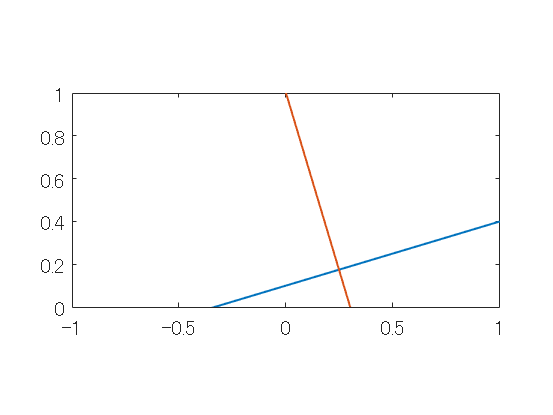

zx = 10;
zz = 3;
x = -5:5;
z = zz/zx * x+0.1;
plot(x, z); xlim([-1 1]); ylim([0 1])
hold on;
daspect([1,1,1]);
Rz = -(zx/zz) * x+ 1;
plot(x, Rz);
hold off;


-(zx/zz) * 27/109 + 1

ans = 0.1743


theta_rad = atan2(zz, zx)

theta_rad = 0.2915

theta_deg = rad2deg(atan2(zz, zx))

theta_deg = 16.6992


zz/zx*27/109+0.1

ans = 0.1743

zz/zx * -0.0877+0.1

ans = 0.0737

0.1557 - (zz/zx * -0.0877+0.1)

ans = 0.0820

x = 0:0.1:5;
zz = 0.3;
z = exp(-x/zz)+0.1;
10*exp(-3/zz)+0.1

ans = 0.1005

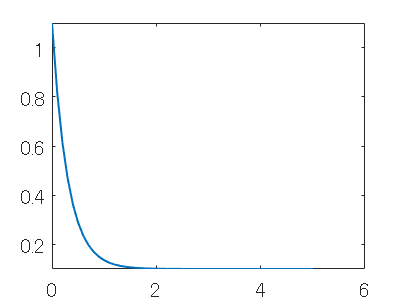

plot(x, z);
ylim([-inf inf])


syms zt real 
z = exp(-zt/zz);
zdt = diff(z, zt)

$$zdt = -\frac{10\,{\mathrm{e}}^{-\frac{10\,\mathrm{zt}}{3}}}{3}$$

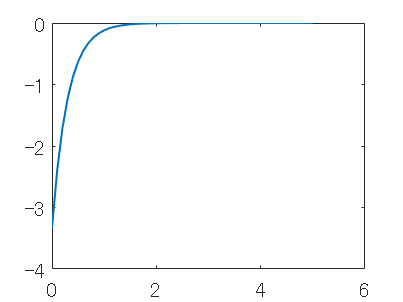

Zdt = subs(zdt, zt, x);
plot(x, Zdt);

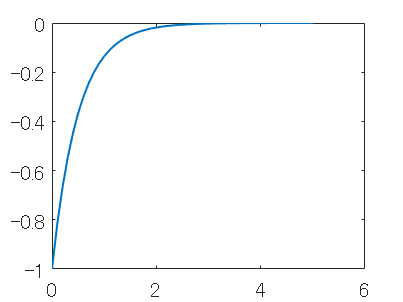


x = 0:0.1:5;
zz = 0.6;
z = -exp(-x/0.5);
plot(x, z);

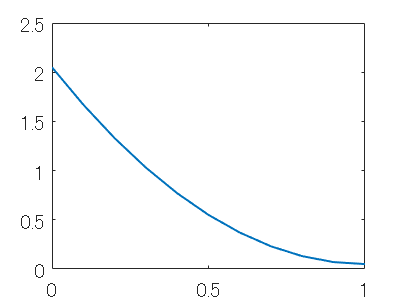


t = 0:0.1:1;
z = 2 * (t-1).^2 + 0.05;
plot(t, z);

xx = -5:5;
yy = zeros(1, size(xx, 2))

yy =      0     0     0     0     0     0     0     0     0     0     0


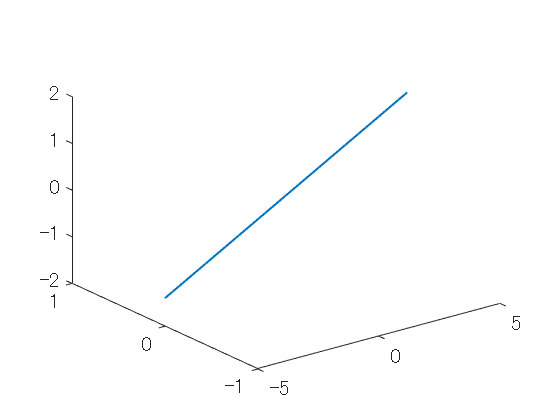

zz = 3/10 * xx+0.1;
plot3(xx, yy, zz);

T = cell(2,1);
T{1,1} = @(x, y) x^2 + y^2 + 1;
T{2,1} = @(x) x^2 + 1;
T

T = 2×1 の cell 配列
    {@(x,y)x^2+y^2+1}
    {      @(x)x^2+1}


T{1,1}(2, 1)

ans = 6

T{2,1}(5)

ans = 26

% B = T{:,1}([2, 2])

% for j = 1:10000
%     pathJN_1(j) = pathJN{1}(1, j);
%     pathJN_2(j) = pathJN{1}(1,j)*data.variable_particle_num(1)*10000;
%     path_color(j) = ceil(pathJN{1}(1,j)*data.variable_particle_num(1)+10000.0001);
% end

変数 'pathJN' は未定義です。

A = [1,2,3;2,1,3;6,3,2;1,4,19]

A =      1     2     3
     2     1     3
     6     3     2
     1     4    19


min(A)

ans =      1     1     2



B = [1, 2 ,4, 2, 9];
min(B)

ans = 1

min(B, 1:3)

配列のサイズがこの演算に適合しません。

関連ドキュメンテーション